## **Fixed point Iteration Method**: 

The transcendental equation f(x) = 0 can be converted algebraically into the form x = g(x) and then using the iterative scheme with the recursive relation

                              xi+1 = g(xi)     , i = 0, 1, 2 ,3, . . . . . .

with some initial guess x0 is called the fixed point iterative scheme.

### **Fixed Point**:

A fixed point for a function is a number at which the value of the function does not change when the function is applied. That means x = f(x). 

### **Method**:

Suppose we have an equation f(x) = 0, for which we have to find the solution. The equation can be expressed as x = g(x). Choose g(x) such that |g’(x)| < 1 at x = xo where xo, is some initial guess called fixed point iterative scheme. Then the iterative method is applied by successive approximations given by xn = g(xn-1), that is, x1 = g(xo), x2 = g(x1) and so on.

### **Algorithm of Fixed Point Iteration Method**: 

1) Choose the initial value xofor the iterative method. One way to choose xo is to find the values x = a and x = b for which f(a) < 0 and f(b) > 0. By narrowing down the selection of a and b, take xo as the average of a and b.

2) Express the given equation, in the form x = g(x) such that |g’(x)| < 1 at x = xo. If there more than one possibility of g(x), choose the g(x) which has the minimum value of g’(x) at x = xo.

3) By applying the successive approximations xn = g (xn-1), if f is a continuous function, we get a sequence of {xn} which converges to a point lo, which is the approximate solution of the given equation.

**Some interesting facts about the fixed point iteration method are - 

1)The form of x = g(x) can be chosen in many ways. But we choose g(x) for which |g’(x)|<1 at x = xo.

2)By the fixed-point iteration method, we get a sequence of xn, which converges to the root of the given equation.

3)Lower the value of g’(x), fewer the iterations are required to get the approximate solution.

4)The rate of convergence is more if the value of g’(x) is smaller.

5)The method is useful for finding the real roots of the equation, which is the form of an infinite series.

6)The type of convergence seen is linear.

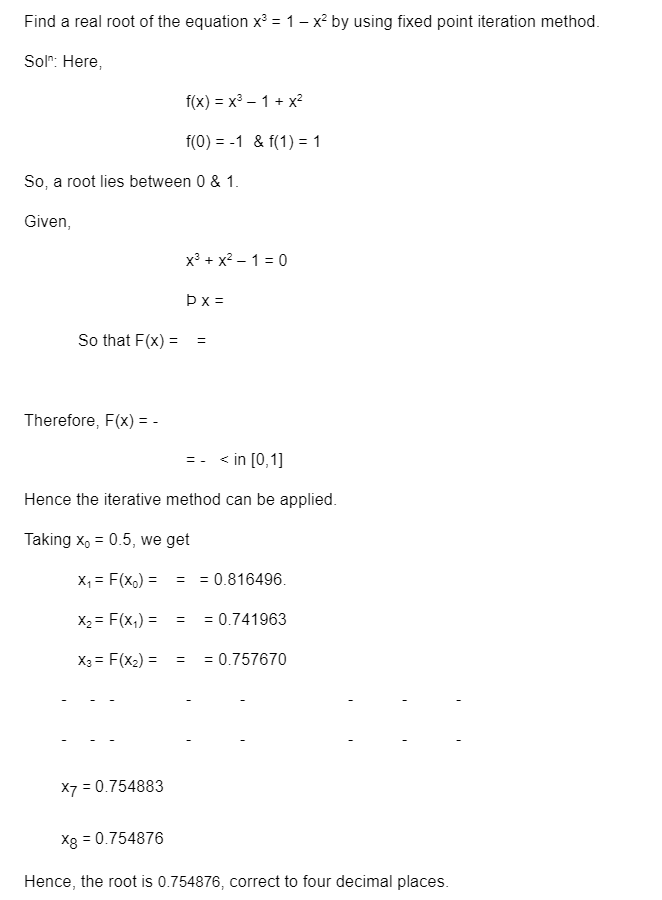

load data_fixed_point_iteration.mat
fixed_point_iteration(x0,maxIter,tol)

Iteration 1: x = 0.44721
Iteration 2: x = 0.83125
Iteration 3: x = 0.73897
Iteration 4: x = 0.75832
Iteration 5: x = 0.75414
Iteration 6: x = 0.75504
Iteration 7: x = 0.75484
Iteration 8: x = 0.75489
Iteration 9: x = 0.75488
Iteration 10: x = 0.75488
Iteration 11: x = 0.75488
The root is approximately 0.75488 after 11 iterations.


function fixed_point_iteration(x0,maxIter,tol)
%f = @(x) x^3 + x^2 - 1;
g = @(x) sqrt(1/(1+x));
%x0 = input('Enter initial guess: ');
%maxIter = input('Enter maximum number of iterations: ');
%tol = input('Enter tolerance: ');
iter = 0;
err = inf;

while iter < maxIter && err > tol
    x1 = g(x0);
    err = abs(x1 - x0);
    iter = iter + 1;
    x0 = x1;
    disp(['Iteration ', num2str(iter), ': x = ', num2str(x0)])
end
disp(['The root is approximately ', num2str(x0), ' after ', num2str(iter), ' iterations.'])
end
